# EXP.4.Sensor Data Acquisition

Open port

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(s,'CR') % end lines with \r

Prompt the user for sample rate and number of samples and send to the Pico.

sample_rate = input("Please enter the sample rate: ")

sample_rate = 2

N = input("Please enter the number of samples: ")

N = 60

s.writeline(string(sample_rate))
s.writeline(string(N))

Receive results and store them in two arrays sensor1 and sensor2.

sensor1 = zeros(1,N);

sensor1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensor2 = zeros(1,N);

sensor2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for k = 1:N
    sensor1(1,k) = s.readline();
    sensor2(1,k) = s.readline();
end
sensor1

sensor1 =        60846       60942       60958       61150       60942       60814       60974       60942       60974       60974       61006       60878       60990       61006       60990       61022       61166       61086       61086       60894       60878       60958       60942       60942       61214       60958       60878       61118       60894       60894       60862       60894       60734       60862       60862       60734       60734       60830       60862       60878       60814       60782       60782       60750       60974       60766       60686       60750       60654       60686


sensor2

sensor2 =        60814       60782       60846       60846       60862       60830       60702       60830       60862       60734       60878       60846       60862       61102       60862       60878       60942       60846       60942       60862       60830       60766       60814       60862       60830       60830       60750       60766       60942       60718       60718       60638       60702       60718       60718       60718       60686       60638       60734       60686       60686       60638       60654       60622       60606       60638       60622       60606       60654       60638


Convert sensor1 and sensor2 to degrees Fahrenheit and store in temp1 and temp2.

temp1 = convert_to_temp(sensor1)

temp =    91.8296   92.6997   92.8447   94.5850   92.6997   91.5395   92.9897   92.6997   92.9897   92.9897   93.2798   92.1196   93.1348   93.2798   93.1348   93.4248   94.7300   94.0049   94.0049   92.2646   92.1196   92.8447   92.6997   92.6997   95.1651   92.8447   92.1196   94.2949   92.2646   92.2646   91.9746   92.2646   90.8144   91.9746   91.9746   90.8144   90.8144   91.6845   91.9746   92.1196   91.5395   91.2495   91.2495   90.9594   92.9897   91.1045   90.3793   90.9594   90.0893   90.3793


temp1 =    91.8296   92.6997   92.8447   94.5850   92.6997   91.5395   92.9897   92.6997   92.9897   92.9897   93.2798   92.1196   93.1348   93.2798   93.1348   93.4248   94.7300   94.0049   94.0049   92.2646   92.1196   92.8447   92.6997   92.6997   95.1651   92.8447   92.1196   94.2949   92.2646   92.2646   91.9746   92.2646   90.8144   91.9746   91.9746   90.8144   90.8144   91.6845   91.9746   92.1196   91.5395   91.2495   91.2495   90.9594   92.9897   91.1045   90.3793   90.9594   90.0893   90.3793


temp2 = convert_to_temp(sensor2)

temp =    91.5395   91.2495   91.8296   91.8296   91.9746   91.6845   90.5244   91.6845   91.9746   90.8144   92.1196   91.8296   91.9746   94.1499   91.9746   92.1196   92.6997   91.8296   92.6997   91.9746   91.6845   91.1045   91.5395   91.9746   91.6845   91.6845   90.9594   91.1045   92.6997   90.6694   90.6694   89.9443   90.5244   90.6694   90.6694   90.6694   90.3793   89.9443   90.8144   90.3793   90.3793   89.9443   90.0893   89.7993   89.6542   89.9443   89.7993   89.6542   90.0893   89.9443


temp2 =    91.5395   91.2495   91.8296   91.8296   91.9746   91.6845   90.5244   91.6845   91.9746   90.8144   92.1196   91.8296   91.9746   94.1499   91.9746   92.1196   92.6997   91.8296   92.6997   91.9746   91.6845   91.1045   91.5395   91.9746   91.6845   91.6845   90.9594   91.1045   92.6997   90.6694   90.6694   89.9443   90.5244   90.6694   90.6694   90.6694   90.3793   89.9443   90.8144   90.3793   90.3793   89.9443   90.0893   89.7993   89.6542   89.9443   89.7993   89.6542   90.0893   89.9443


Create a time series using linspace based on the number of samples and sample rate. All

three arrays should have the same number of elements.

time = linspace(0,N/sample_rate,N)

time =          0    0.5085    1.0169    1.5254    2.0339    2.5424    3.0508    3.5593    4.0678    4.5763    5.0847    5.5932    6.1017    6.6102    7.1186    7.6271    8.1356    8.6441    9.1525    9.6610   10.1695   10.6780   11.1864   11.6949   12.2034   12.7119   13.2203   13.7288   14.2373   14.7458   15.2542   15.7627   16.2712   16.7797   17.2881   17.7966   18.3051   18.8136   19.3220   19.8305   20.3390   20.8475   21.3559   21.8644   22.3729   22.8814   23.3898   23.8983   24.4068   24.9153


Plot both temperatures vs. time. Make sure to include axis labels, legend, and title.

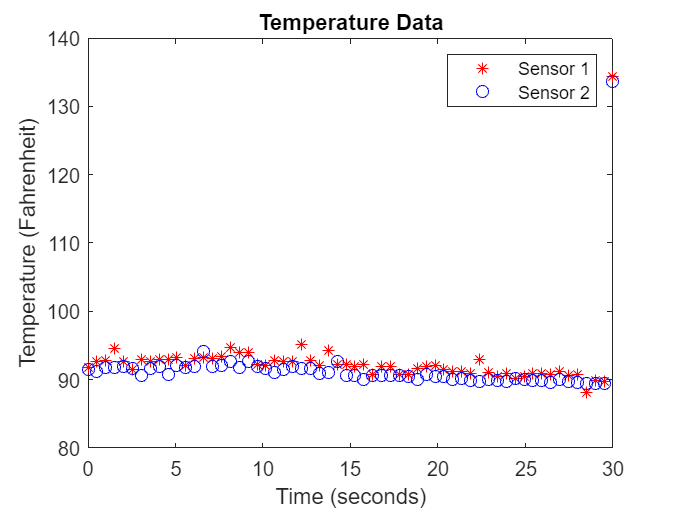

plot(time,temp1,'r*')
hold on
plot(time,temp2,'bo')
hold off
title("Temperature Data")
legend(["Sensor 1", "Sensor 2"])
xlabel("Time (seconds)")
ylabel("Temperature (Fahrenheit)")

function temp = convert_to_temp(n)

    temp = (((1/0.01)*((3.3/65535).*n) - 273.15)*(9/5)) + 32;

end